1.

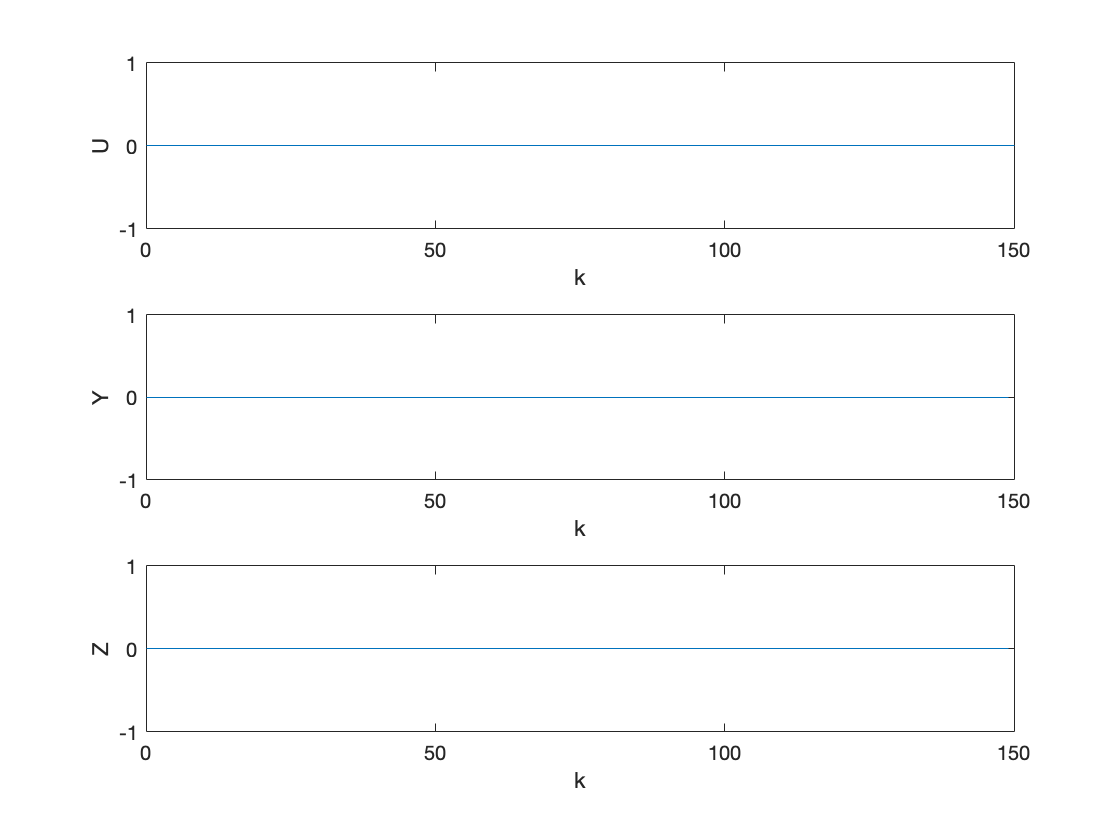

Upp = 0;
Ypp = 0;
Zpp = 0;
% Umin = 0.6;
% Umax = 1.2;
Tp = 0.5;
imax = 150;
Y = zeros(1, imax);
U = zeros(1, imax+1);
Z = zeros(1, imax);
Y(1:2) = Ypp;
Z(1:4) = Zpp;
U(1:imax+1) = Upp;
for i = 5:imax
%     Y(i) = symulacja_obiektu2Y_p1(Upp, Upp, Y(i-1), Y(i-2));
    Y(i)=symulacja_obiektu2y_p2(Upp,Upp,Zpp,Zpp,Y(i-1),Y(i-2));

end
subplot(3,1,1);
stairs(0:length(U)-1, U);
xlabel('k');
ylabel('U');
hold on
subplot(3,1,2);
stairs(0:length(Y)-1, Y);
xlabel('k');ylabel('Y');
hold on
subplot(3,1,3);
stairs(0:length(Z)-1, Z);
xlabel('k');
ylabel('Z');
hold off

2. 

dla toru U-Y

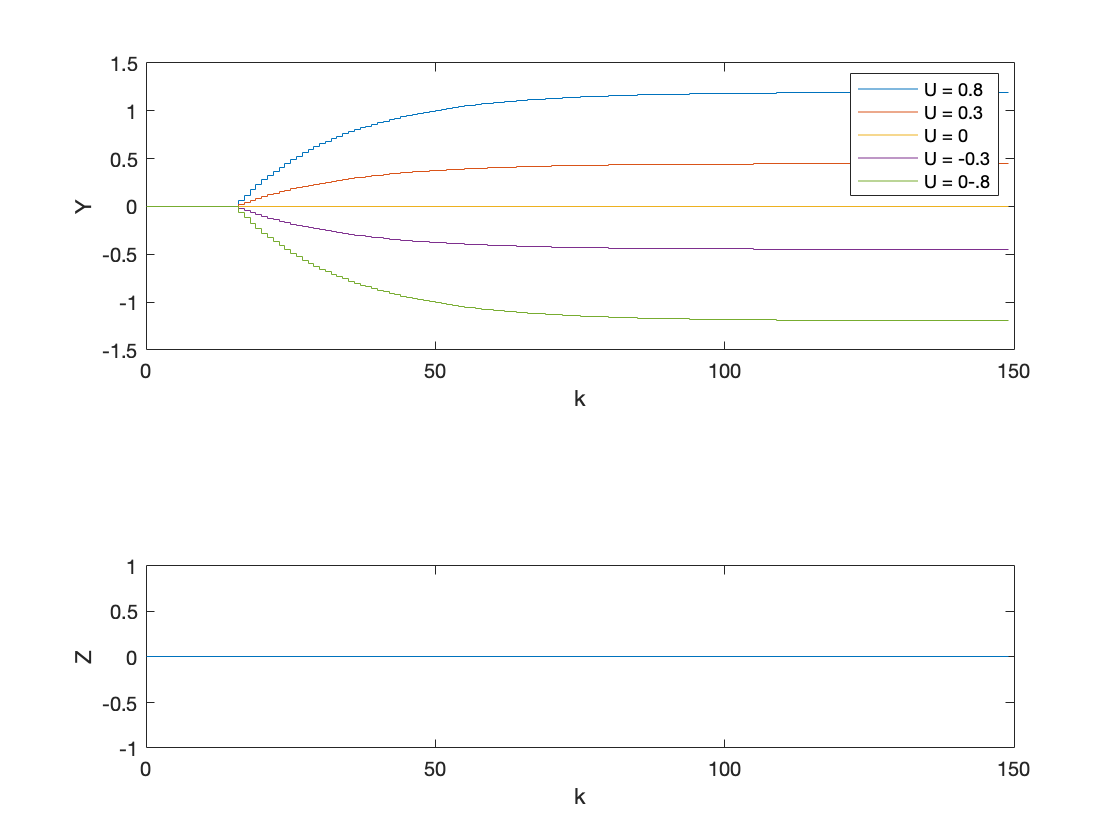

Yu = zeros(1,5);
Uu = [0.8, 0.3, Upp, -0.3, -0.8];
Y = zeros(1, imax);
U = zeros(1, imax);
Z = zeros(1, imax);
U(1:11) = Upp;
Y(1:11) = Ypp;

for i = 1:5
    U(12:imax)= Uu(i);
    for k = 12:imax
        Y(k)=symulacja_obiektu2y_p2(U(k-5),U(k-6),Z(k-3),Z(k-4),Y(k-1),Y(k-2));
    end
    
    Yu(i) = Y(imax);

    subplot(2,1,1);
    stairs(0:length(Y)-1, Y);
    hold on;   
end
legend("U = 0.8", "U = 0.3", "U = 0", "U = -0.3", "U = 0-.8")
xlabel("k")
ylabel("Y")

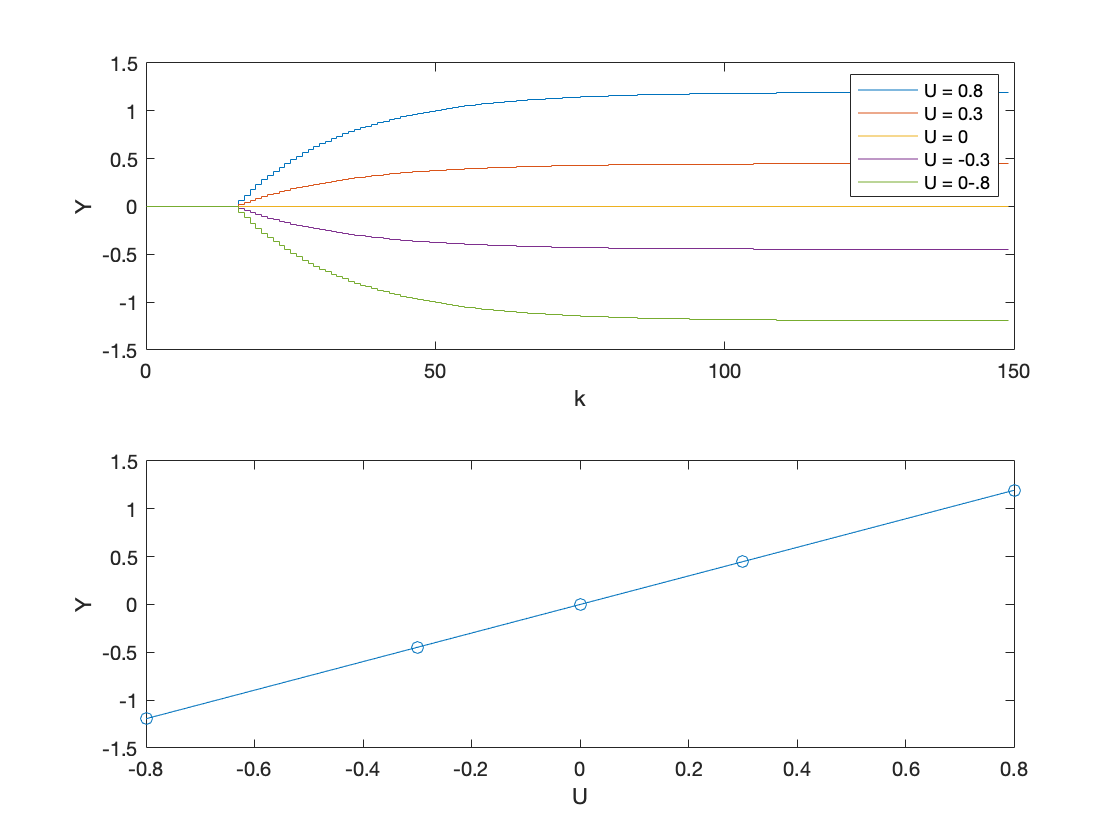

subplot(2,1,2);
plot(Uu, Yu, "o");
hold on
xlabel("U");
ylabel("Y");
lsline;
hold off


Kstat=(Yu(5)-Yu(1))/(Uu(5)-Uu(1))

Kstat = 1.4925

dla toru Z-Y

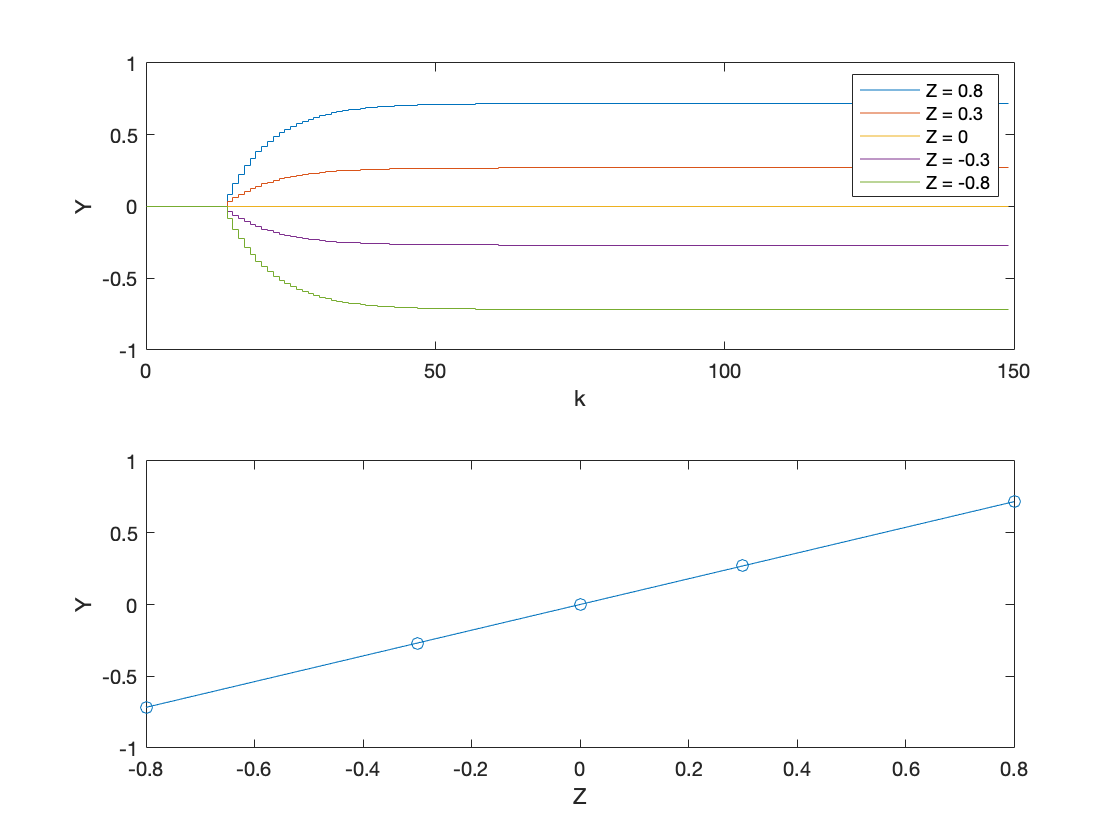

Yu = zeros(1,5);
Zu = [0.8, 0.3, Zpp, -0.3, -0.8];
Y = zeros(1, imax);
U = zeros(1, imax);
Z = zeros(1, imax);
U(1:11) = Upp;
Y(1:11) = Ypp;

figure(2)

for i = 1:5
    Z(12:imax)= Zu(i);
    for k = 12:imax
        Y(k)=symulacja_obiektu2y_p2(U(k-5),U(k-6),Z(k-3),Z(k-4),Y(k-1),Y(k-2));
    end
    
    Yu(i) = Y(imax);

    subplot(2,1,1);
    stairs(0:length(Y)-1, Y);
    hold on;   
end
legend("Z = 0.8", "Z = 0.3", "Z = 0", "Z = -0.3", "Z = -0.8")
xlabel("k")
ylabel("Y")
subplot(2,1,2);
plot(Zu, Yu, "o");
hold on
xlabel("Z");
ylabel("Y");
lsline;
hold off


Kstat=(Yu(5)-Yu(1))/(Zu(5)-Zu(1))

Kstat = 0.8959